## 描述性统计

### 计算最大值、均值和标准差

% 加载样本数据
load count.dat
% 找出每列的最大值
mx = max(count)
% 计算每列的均值
mu = mean(count)
% 计算每列的标准差
sigma = std(count)

mx =    114   145   257


mu =   32.000000000000000  46.541666666666664  65.583333333333329


sigma =   25.370301021332867  41.405711816300084  68.028073914963301


### 定位每个数据列中最大值出现的位置

要找出整个 count 矩阵（24×3 矩阵）中的最小值，可以使用语法 `count(:)`将其转换为 72×1 的列向量。然后，在这个单列中查找最小值。

clear;
clc;
% 加载样本数据
load count.dat
% 找出每列的最大值
mx = max(count)
% 计算每列的均值
mu = mean(count)
% 计算每列的标准差
sigma = std(count)
[mx,indx] = max(count)
min(count(:))

mx =    114   145   257


mu =   32.000000000000000  46.541666666666664  65.583333333333329


sigma =   25.370301021332867  41.405711816300084  68.028073914963301


mx =    114   145   257


indx =     20    20    20


ans =      7


### 回顾数据去趋势，另一种方法是从每列中减去均值 

% 加载样本数据
load count.dat
% 获取 count 矩阵的大小
[n,p] = size(count)
% 计算每列的均值
mu = mean(count)
% 通过将 mu 向量复制 n 行来创建均值矩阵
MeanMat = repmat(mu,n,1)
% 从每列中的每个元素减去该列的均值
x = count - MeanMat

n = 24

p = 3

mu =    32.0000   46.5417   65.5833


MeanMat =    32.0000   46.5417   65.5833
   32.0000   46.5417   65.5833
   32.0000   46.5417   65.5833
   32.0000   46.5417   65.5833
   32.0000   46.5417   65.5833
   32.0000   46.5417   65.5833
   32.0000   46.5417   65.5833
   32.0000   46.5417   65.5833
   32.0000   46.5417   65.5833
   32.0000   46.5417   65.5833


x =   -21.0000  -35.5417  -56.5833
  -25.0000  -33.5417  -54.5833
  -18.0000  -29.5417  -45.5833
  -21.0000  -33.5417  -56.5833
   11.0000    4.4583    3.4167
    6.0000   -0.5417   10.4167
   29.0000   85.4583  120.4167
   43.0000   88.4583  114.4167
    6.0000   41.4583   49.4167
   -4.0000  -10.5417  -10.5833


### 示例：计算和绘制描述性统计

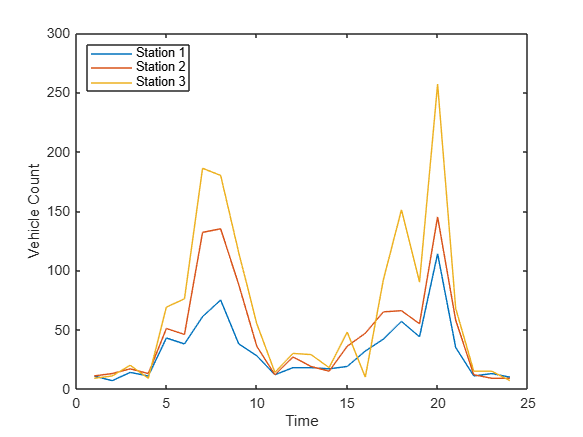

load count.dat
[n,p] = size(count);
% 定义 x 值
t = 1:n;
% 绘制数据并标注图形
plot(t,count)
legend('Station 1','Station 2','Station 3','Location','northwest')
xlabel('Time')
ylabel('Vehicle Count')